**0. Preparation**

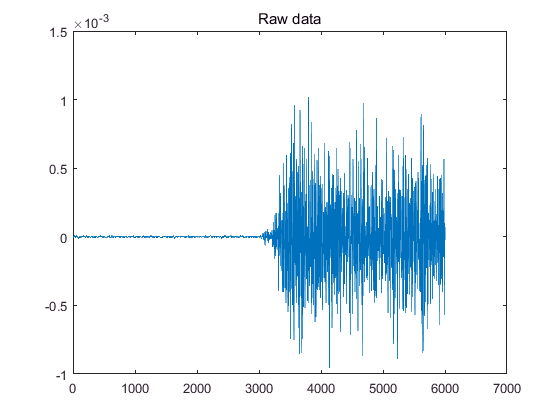

clear, close all,clc

% load data and preview
load('part_ch1.mat');

x = part_ch1;
clear part_ch1;

plot(x);title('Raw data')

**1. Wavelet ChangePoint Detection**

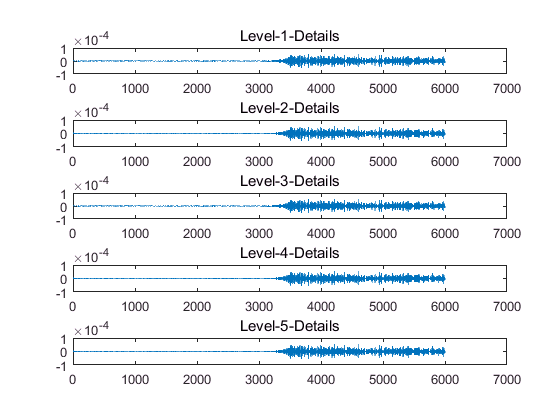

wavename = 'sym4';
level = 4;
wt = modwt(x, wavename, level);
% multi-resolution-analysis
mra = modwtmra(wt, wavename);

figure;
N = size(wt, 1);
for n=1:N
    subplot(N,1,n);
    plot(mra(1,:)); title(['Level-', num2str(n), '-Details']);
end

for JJ = 1:N
    pts_Opt = wvarchg(wt(JJ,:), 2);
    changepoints{JJ} = pts_Opt;
end
Position = cellfun(@(x) ~isempty(x), changepoints, 'uni', 0);
cell2mat(changepoints)

ans =         3134        3103

**2. Wave ChangePoint Detection on Contracted Motions data**

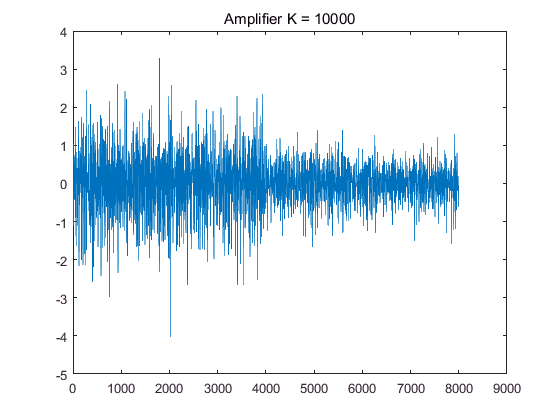

load('ch1RestMotion1234.mat');
figure;
ch1Motion1234 = [ch1Motion2;ch1Motion4];
% Amplified
K = 10000;
ch1Motion1234 = ch1Motion1234*K;
plot(ch1Motion1234); title('Amplifier K = 10000');

2.1 Connected data -- Wavelet ChangePoint Detection

wavename = 'haar';
level = 10;
wt_ch1Motion1234 = modwt(ch1Motion1234, wavename, level);
% multi-resolution-analysis
mra_ch1Motion1234 = modwtmra(wt_ch1Motion1234, wavename);
N = size(wt_ch1Motion1234,1);
for JJ = 1:N
    pts_Opt = wvarchg(wt_ch1Motion1234(JJ,:),3, 50);
    changepoints{JJ} = pts_Opt;
end
Position = cellfun(@(x) ~isempty(x), changepoints, 'uni', 0);
ChangePoint = cell2mat(changepoints)

ChangePoint =         3987        3989        3949        3953        3960        6333        4074        5416        4380        5697        6347        1942        6010

2.2 **Find big variances on different scales.**

tspre = ch1Motion1234(1:ChangePoint(1));
tspost = ch1Motion1234(ChangePoint(1)+1:end);

wpre = modwt(tspre, wavename, level);

错误使用 modwt (line 105)
Invalid transform level.

% wavelet decomposition preview
for n=1:level+1
    subplot(level+1,1,n);
    plot(wpre(n,:));
end
wvarpre = modwtvar(wpre, wavename, 0.95, 'table')
var(wpre(1,:)),var(wpre(2,:)), var(wpre(3,:)),var(wpre(4,:))

    **Got Understood! **

    Variance, 表示分解结果系数序列的方差，上下为置信区间；

% wvarpre = modwtvar(wpre, wavename, 0.01, 'table')
wpost = modwt(tspost, wavename, level);
figure;
% wavelet decomposition preview
for n=1:level+1
    subplot(level+1,1,n);
    plot(wpost(n,:));
end
wvarpost = modwtvar(wpost, wavename, 0.95, 'table')

2.3 **Compare pre- and post- results on variance**

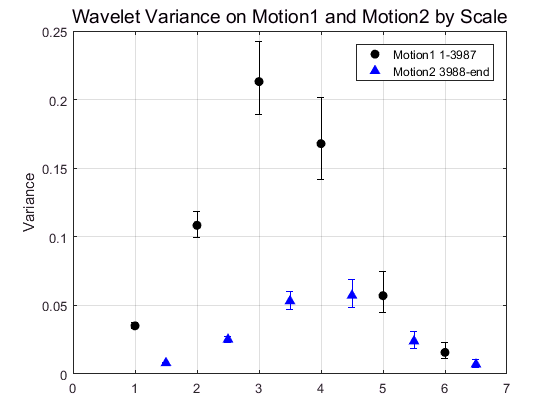

Vpre = table2array(wvarpre);
Vpre = Vpre(1:end-1, 2:end);
Vpre(:,1) = Vpre(:,2) - Vpre(:,1);
Vpre(:,3) = Vpre(:,3) - Vpre(:,2);


Vpost = table2array(wvarpost);
Vpost = Vpost(1:end-1, 2:end);
Vpost(:,1) = Vpost(:,2) - Vpost(:,1);
Vpost(:,3) = Vpost(:,3) - Vpost(:,2);

figure;
errorbar(1:level,Vpre(:,2),Vpre(:,1),Vpre(:,3),'ko','markerfacecolor',[0 0 0]);
hold on;
errorbar(1.5:.5+level,Vpost(:,2),Vpost(:,1),Vpost(:,3),'b^','markerfacecolor',[0 0 1]);
legend('Motion1 1-3987','Motion2 3988-end','Location','NorthEast');
grid on;
ylabel('Variance');
title('Wavelet Variance on Motion1 and Motion2 by Scale','fontsize',14);